# Virtual Species Generation

Here is a step-by-step guide portraying how to generate virtual species using three different methods.

All functions mentioned are documented and explain the optional and required inputs, the description, the outputs and the default values.

## Preparing environment

### 1. Clear command window, workspace variables, and close all figures

clear; clc; close all;

### 2. Set the path to the folder containing the layer data

layerfolder = '../VirtualSpeciesGeneration/data/Capas_Colombia_30S/';

### 3. Read in the layer data from the specified folder using ReadLayers:

-  To execute ReadLayers, there is one required input and three optional inputs.

                Layers = ReadLayers(layer_folder, parallel, nanvalue)

Layers = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 10.781787 seconds.


## Niche generation

### 1. Generate initial point for niche generation using a virtual species method.

- To execute InitialPoint, there is one required input and six optional inputs.

- The default value for method is 'coeff'

 InitialPoint = InitialPoint(layers, method, plotting, random_point, point, coeff, deformations_limit)

#### 1.1 Using Random Coefficients

InfoInitialPoint = InitialPoint(Layers, 'coeff');

Elapsed time is 17.536769 seconds.


#### 1.2 To use the Beta Deformations method:

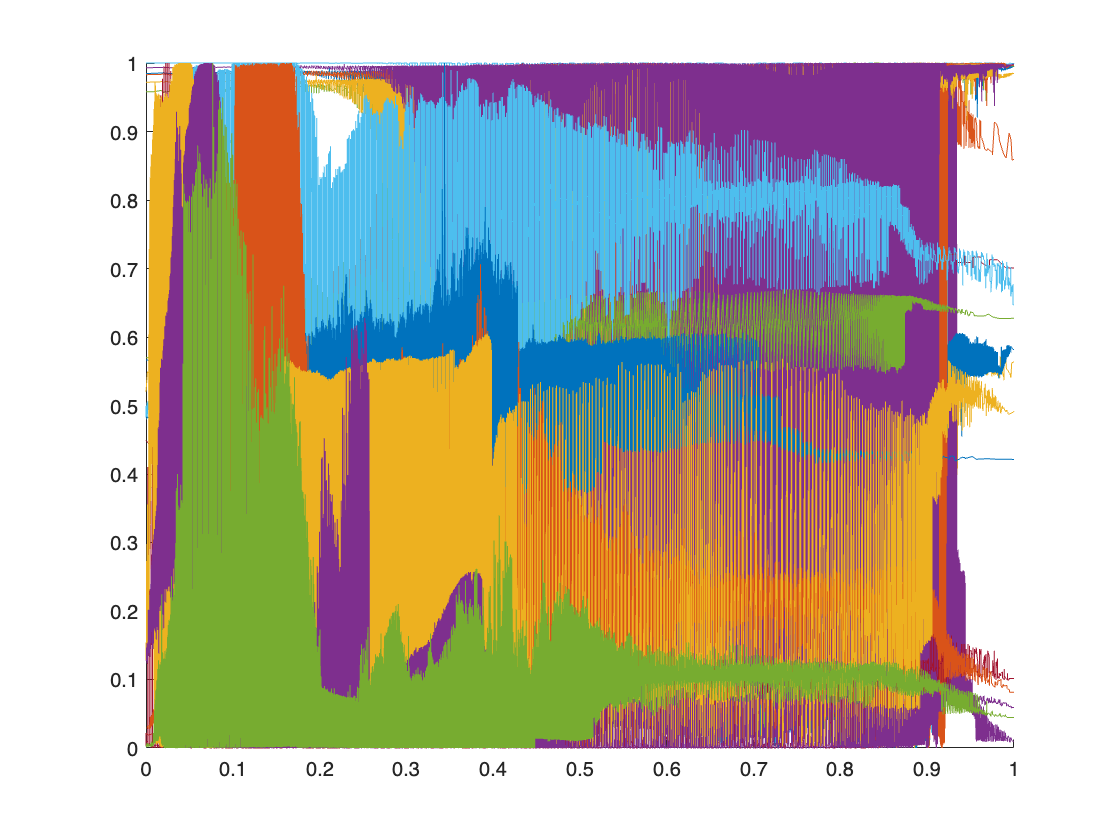

Elapsed time is 26.879919 seconds.


InfoInitialPoint = InitialPoint(Layers,'beta', false);

#### 1.3 To use the Harmonic Deformations method:

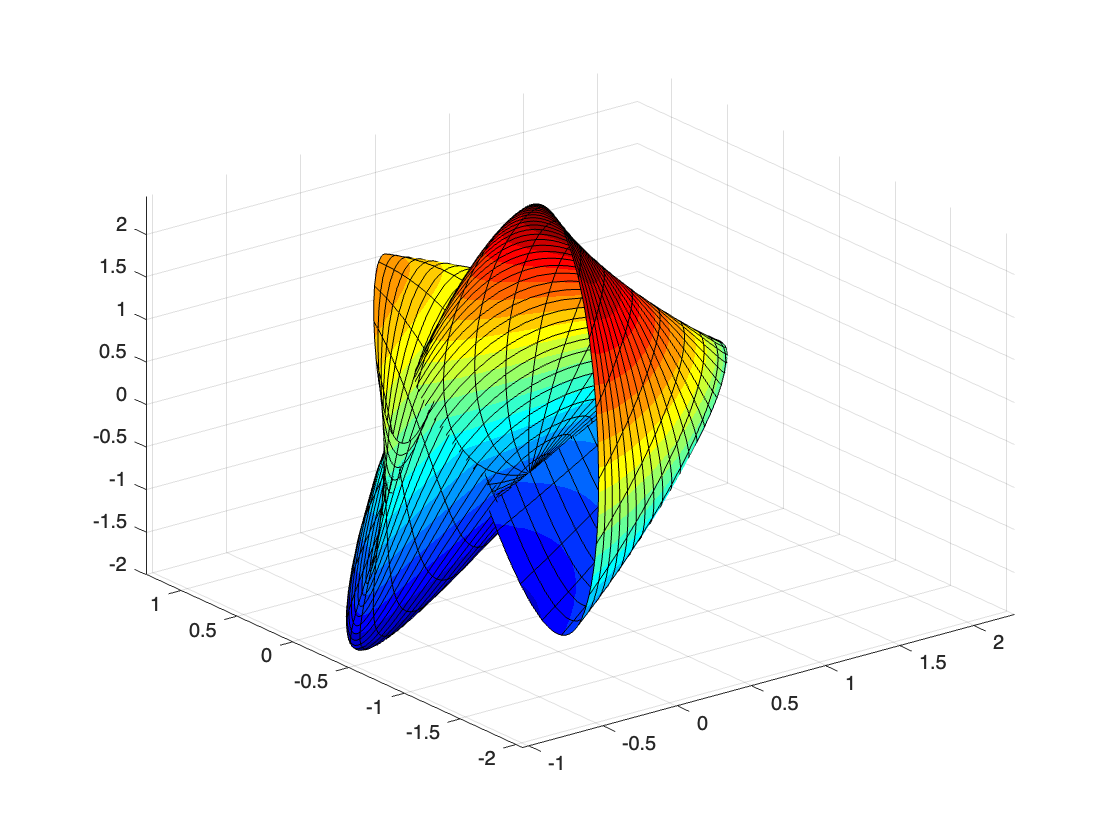

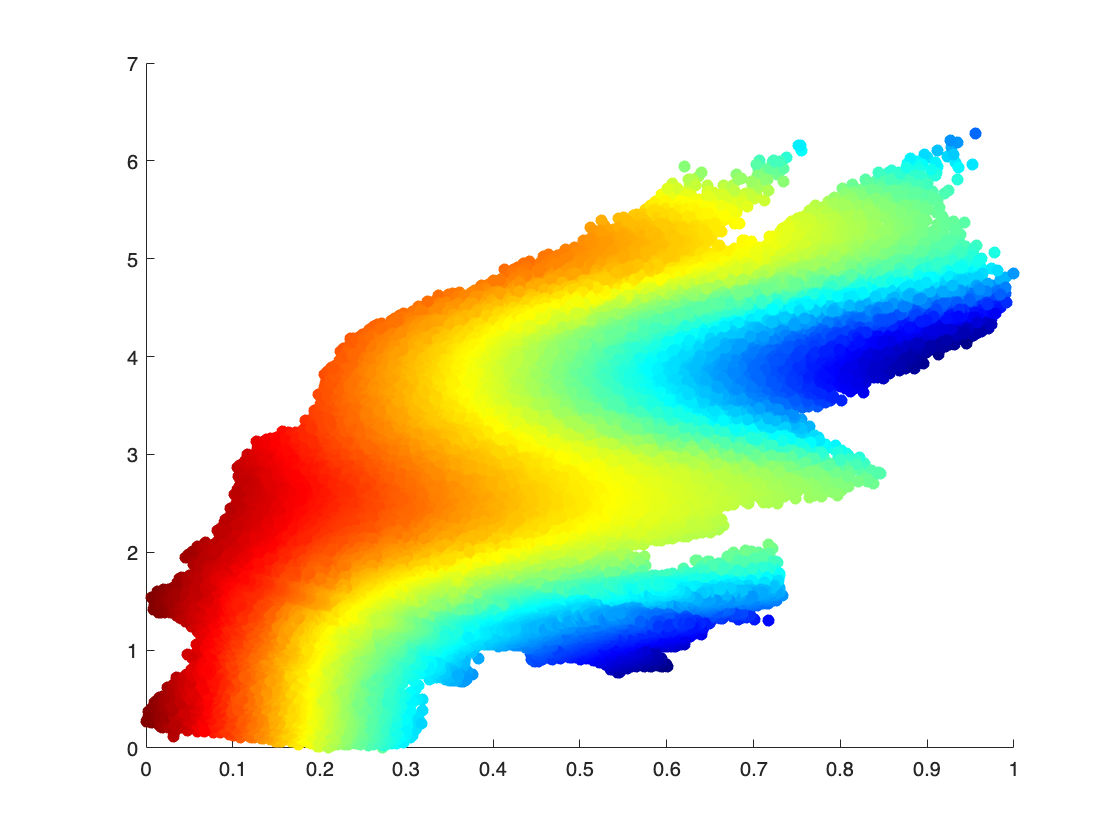

Elapsed time is 21.381711 seconds.


clf
InfoInitialPoint = InitialPoint(Layers,'harmonic', true);

### 2. Generate the niche map using niche generation algorithm with the initial point

Map = NicheGeneration(Layers, InitialPoint, occupation, plotting)

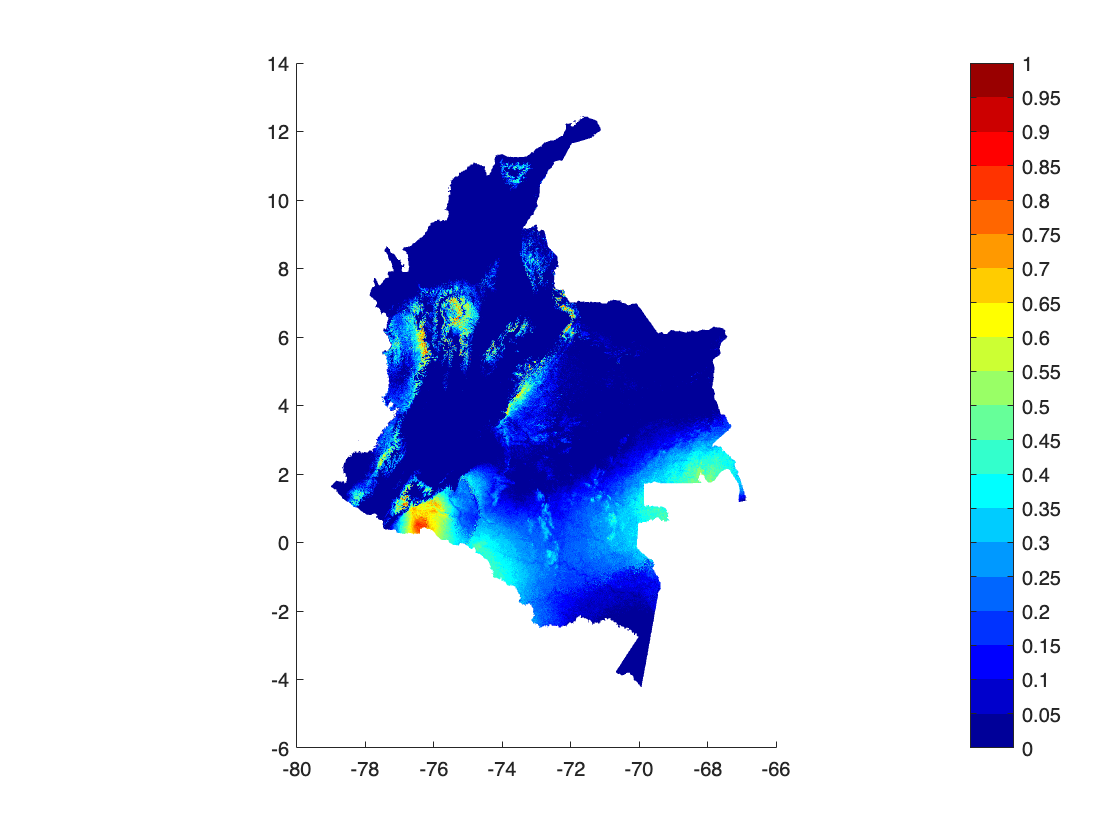

Elapsed time is 2.853745 seconds.


MapInfo = NicheGeneration(Layers, InfoInitialPoint, 0.5, true);

### 3. Sample virtual species using the generated niche map

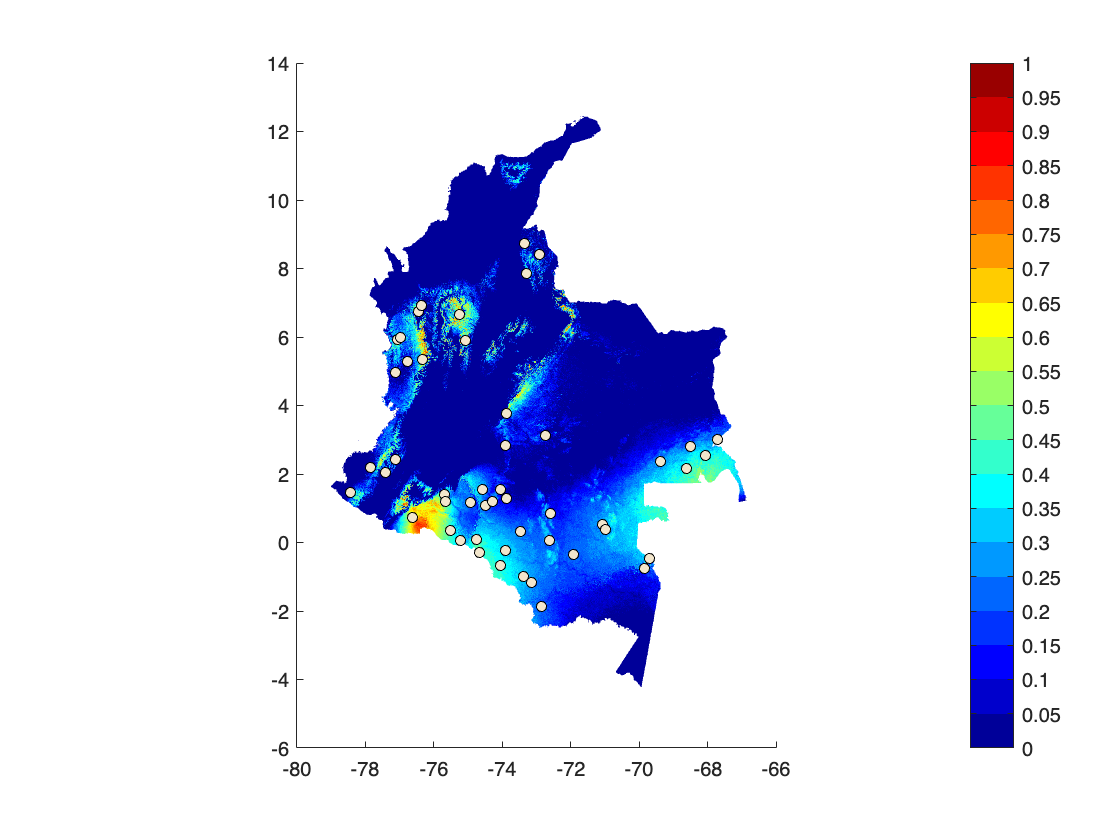

T = samplingVS(Layers, InfoInitialPoint, MapInfo, 50, -1, true, 'GenSP', true, true);